# Polarization Vision in Terrestrial Hermit Crabs

*Martin J. How, Alasdair Robertson, Samuel P. Smithers, David Wilby*

Execute the code in the cells below in order to perform the analysis and produce figure 1 from the paper.

Firstly, ensure that any dependencies are installed.

assert(isToolboxAvailable('Statistics and Machine Learning Toolbox', 'error'))

Make sure that the project is loaded.

openProject('HermitCrabPolVisionMATLAB.prj')

ans =   Project with properties:

                        Name: "HermitCrabPolVision"
    SourceControlIntegration: "Git"
          RepositoryLocation: "https://github.com/davidwilby/HermitCrabPolarizationVision2022.git"
       SourceControlMessages: ["Branch status: Normal"    "No remote tracking branch"    "Current branch: matlab_deps"]
                    ReadOnly: 0
                    TopLevel: 1
                Dependencies: [1×1 digraph]
                  Categories: [1×1 matlab.project.Category]
                       Files: [1×11 matlab.project.ProjectFile]
                   Shortcuts: [1×0 matlab.project.Shortcut]
                 ProjectPath: [1×4 matlab.project.PathFolder]
           ProjectReferences: [1×0 matlab.project.ProjectReference]
                StartupFiles: [1×0 string]
               ShutdownFiles: [1×0 string]
         DefinitionFilesType: FixedPathMultiFile
                 Descri

Then run the main function to produce the graphs.

loading data/20200212_PaleHermitCrab2/20200212_174758_hermit07_p.mat 


loading data/20200212_PaleHermitCrab2/20200212_181001_hermit02_p.mat 


loading data/20200212_PaleHermitCrab2/20200212_183136_hermit01_p.mat 


loading data/20200212_PaleHermitCrab2/20200213_093954_hermit05_p.mat 


loading data/20200212_PaleHermitCrab2/20200213_100640_hermit04_p.mat 


loading data/20200212_PaleHermitCrab2/20200213_103126_hermit06_p.mat 


loading data/20200212_PaleHermitCrab2/20200213_105319_hermit08_p.mat 


loading data/20200212_PaleHermitCrab2/20200213_123144_hermit09_p.mat 


loading data/20200212_PaleHermitCrab2/20200213_125353_hermit10_p.mat 


loading data/20200212_PaleHermitCrab2/20200213_131701_hermit11_p.mat 


loading data/20200212_PaleHermitCrab2/20200213_135058_hermit12_p.mat 


loading data/20200212_PaleHermitCrab2/20200214_195431_hermit20_p.mat 


loading data/20200212_PaleHermitCrab2/20200214_201919_hermit21_p.mat 


loading data/20200212_PaleHermitCrab2/20200215_094230_hermit24_p.mat 


loading data/20200212_PaleHermitCrab2/20200215_100424_hermit25_p.mat 


loading data/20200212_PaleHermitCrab2/20200215_102512_hermit26_p.mat 


loading data/20200212_PaleHermitCrab2/20200215_104622_hermit27_p.mat 


loading data/20200212_PaleHermitCrab2/20200215_110917_hermit28_p.mat 


loading data/20200212_PaleHermitCrab2/20200215_114513_hermit29_p.mat 


loading data/20200212_PaleHermitCrab2/20200215_120616_hermit30_p.mat 


loading data/20200212_PaleHermitCrab2/20200215_122836_hermit31_p.mat 


loading data/20200212_PaleHermitCrab2/20200215_125101_hermit33_p.mat 


loading data/20200212_PaleHermitCrab2/20200216_083056_hermit34_p_.mat 


loading data/20200212_PaleHermitCrab2/20200216_085215_hermit35_p.mat 


loading data/20200212_PaleHermitCrab2/20200216_091258_hermit36_p.mat 


loading data/20200212_PaleHermitCrab2/20200216_093332_hermit37_p.mat 


loading data/20200212_PaleHermitCrab2/20200216_095416_hermit38_p.mat 


loading data/20200212_PaleHermitCrab2/20200216_101432_hermit39_p.mat 


loading data/20200218_PurpleHermit_P/20200218_152743_hermit02_P.mat 


loading data/20200218_PurpleHermit_P/20200218_154313_hermit03_P.mat 


loading data/20200218_PurpleHermit_P/20200218_160650_hermit01_P.mat 


loading data/20200218_PurpleHermit_P/20200218_163913_hermit05_p.mat 


loading data/20200218_PurpleHermit_P/20200218_165440_hermit06_p.mat 


loading data/20200218_PurpleHermit_P/20200218_170929_hermit07_p.mat 


loading data/20200218_PurpleHermit_P/20200218_172543_hermit08_p.mat 


loading data/20200218_PurpleHermit_P/20200220_063348_hermit09_P.mat 


loading data/20200218_PurpleHermit_P/20200220_065330_hermit10_P.mat 


loading data/20200218_PurpleHermit_P/20200220_070854_hermit11_P.mat 


loading data/20200218_PurpleHermit_P/20200220_072241_hermit12_P.mat 


loading data/20200218_PurpleHermit_P/20200220_074353_hermit13_P.mat 


loading data/20200218_PurpleHermit_P/20200220_075943_hermit14_P.mat 


loading data/20200218_PurpleHermit_P/20200220_081745_hermit15_P.mat 


loading data/20200218_PurpleHermit_P/20200220_084737_hermit17_P.mat 


loading data/20200216_PaleHermit4_i/20200216_112856_hermit01_i.mat 


loading data/20200216_PaleHermit4_i/20200216_114437_hermit02_i.mat 


loading data/20200216_PaleHermit4_i/20200216_120232_hermit03_i.mat 


loading data/20200216_PaleHermit4_i/20200216_121725_hermit04_i.mat 


loading data/20200216_PaleHermit4_i/20200216_123213_hermit05_i.mat 


loading data/20200216_PaleHermit4_i/20200216_124714_hermit06_i.mat 


loading data/20200216_PaleHermit4_i/20200216_130231_hermit07_i.mat 


loading data/20200216_PaleHermit4_i/20200216_131729_hermit08_i.mat 


loading data/20200216_PaleHermit4_i/20200216_133234_hermit09_i.mat 


loading data/20200216_PaleHermit4_i/20200216_135310_hermit10_i.mat 


loading data/20200216_PaleHermit4_i/20200216_140825_hermit11_i.mat 


loading data/20200216_PaleHermit4_i/20200216_150214_hermit12_i.mat 


loading data/20200216_PaleHermit4_i/20200216_151735_hermit13_i.mat 


loading data/20200216_PaleHermit4_i/20200216_153220_hermit14_i.mat 


loading data/20200216_PaleHermit4_i/20200217_150142_hermit15_i.mat 


loading data/20200216_PaleHermit4_i/20200217_151734_hermit16_i.mat 


loading data/20200216_PaleHermit4_i/20200217_153945_hermit17_i.mat 


loading data/20200216_PaleHermit4_i/20200217_155711_hermit18_i.mat 


loading data/20200221_PurpleHermit_I/20200221_081634_hermit03_I.mat 


loading data/20200221_PurpleHermit_I/20200221_083110_hermit04_I.mat 


loading data/20200221_PurpleHermit_I/20200221_084511_hermit05_I.mat 


loading data/20200221_PurpleHermit_I/20200221_091340_hermit07_I.mat 


loading data/20200221_PurpleHermit_I/20200221_092722_hermit08_I.mat 


loading data/20200221_PurpleHermit_I/20200221_094135_hermit09_I.mat 


loading data/20200221_PurpleHermit_I/20200221_095656_hermit10_I.mat 


loading data/20200221_PurpleHermit_I/20200221_101110_hermit11_I.mat 


loading data/20200221_PurpleHermit_I/20200221_102444_hermit12_I.mat 


loading data/20200221_PurpleHermit_I/20200221_103915_hermit13_I.mat 


loading data/20200221_PurpleHermit_I/20200221_105236_hermit14_I.mat 


loading data/20200221_PurpleHermit_I/20200221_111411_hermit15_I.mat 


loading data/20200221_PurpleHermit_I/craborder.mat 


ans =     27     9


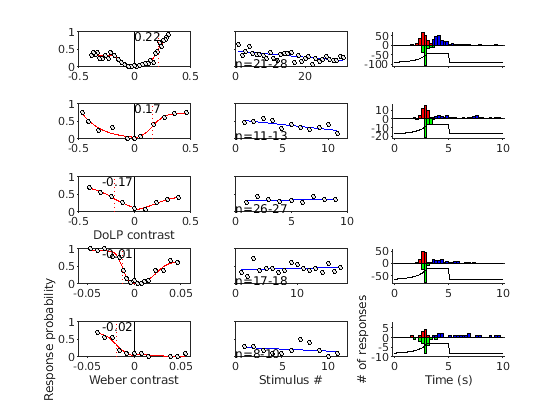

plotHermitCrabFigures